# Expand Example 2.11:

This live script is for use with the textbook

*Continuous-Time Signals and Systems: A MATLAB Integrated Approach*

by Oktay Alkin, CRC Press, 2025.

Consider the RC circuit shown below. The switch is moved from position A to position B at time $t=0$.

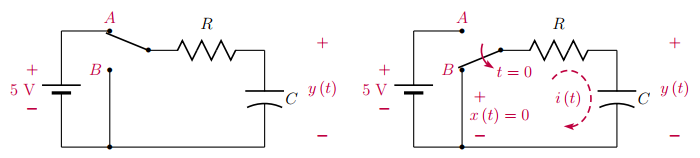

The homogeneous differential equation is in the form

        
$$\frac{dy}{dt}+\frac{1}{RC}\,y(t)=0$$


The homogeneous solution is

        
$$y_{h}(t) = y_{h}(0)\,e^{-t/RC}$$


R = 1; % Resistance
C = 0.25; % Capacitance

y0 = 5; % Initial value

Compute and graph the natural response:

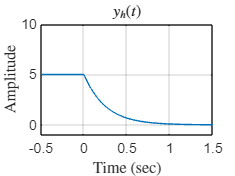

alpha = 1/(R*C);
t = [-0.5:0.005:1.5];
yh = y0*(t<0)+y0*exp(-alpha*t).*(t>=0);
plot(t,yh); grid;
axis([-0.5,1.5,-1,10]);
set(0,'defaultTextInterpreter','latex');
xlabel('Time (sec)');
ylabel('Amplitude');
title('$y_{h}(t)$');

set(0,'defaultTextInterpreter','tex');